## Riccati Differential Equation

#### Idle Mode:


$$\dot{\;\Omega \;} \left(t\right)=A\;\Omega \;\left(t\right)+\Omega \;\left(t\right)A^{T\;} +Q\;$$


Scaler case: $a\gets A,\;q\gets Q,\;\;\Omega {\;}_0 \gets \Omega \left(t_0 \right)$ 


$$\Omega \left(t\right)\;=\left(\Omega {\;}_{0\;} +\frac{q}{2a}\right)e^{2a\left(t-t_{0\;} \right)} -\frac{q}{2a}$$



$$J\left(t_{0\;} ,t_{0\;} +w\right)=\frac{1}{2a}\left(\Omega {\;}_{0\;} +\frac{q}{2a}\right)\left(e^{2\mathrm{aw}} -1\right)-\frac{q}{2a\;}w$$


clear all; close all; clc;

a = 0.2628;
q = 0.8107;
t_0 = 5;
Omega_0 = 1

deltaT = 0.001;
periodT = 10;
Omega = Omega_0;
JArray = []; 
errorFrac = [];
OmegaArray = [];
for w = 0:deltaT:periodT % w = t-t_0
    Omega = Omega + deltaT*(2*a*Omega + q);
    OmegaAct = (Omega_0 + (q/(2*a)))*exp(2*a*w)-(q/(2*a));
    OmegaArray = [OmegaArray, OmegaAct];
    errorFrac = [errorFrac, (OmegaAct-Omega)*100/OmegaAct];
    
    % cost upto w
    J_w = (1/(2*a))*(Omega_0 + (q/(2*a)))*(exp(2*a*w)-1)-(q/(2*a))*w; 
    JArray = [JArray, J_w];
end
figure
plot(0:deltaT:periodT,errorFrac)
ylabel('Percentage Discretization Error')
xlabel('Time: w = t - t_0')
grid on
% Percentage discretization error grows linearly but is less than 1%

figure
plot(0:deltaT:periodT,OmegaArray)
ylabel('\Omega(t)')
xlabel('Time: w = t - t_0')
grid on

figure
plot(0:deltaT:periodT,JArray)
ylabel('J(t_0, t_0+w)')
xlabel('Time: w = t - t_0')
grid on

JArray1 = JArray;

#### Dwell Mode

$\dot{\;\Omega \;} \left(t\right)=A\;\Omega \;\left(t\right)+\Omega \;\left(t\right)A^{T\;} +Q\;-\Omega \;\left(t\right)\;G\;\Omega \left(t\right)$ with $G=H^T R^{-1} H$

Scaler case: $a\gets A,\;q\gets Q,\;\;g\gets G,\;\;\Omega {\;}_0 \gets \Omega \left(t_0 \right)$ 

$v_1 =\frac{1}{q}\left(-a+\sqrt{a^2 +\mathit{qg}}\right)$ and $v_2 =\frac{1}{q}\left(-a-\sqrt{a^2 +\mathit{qg}}\right)$ and $\lambda =2\sqrt{a^2 +\mathit{qg}}$


$$\Omega \left(t\right)\;=\frac{\left(v_2 \;\Omega {\;}_0 -1\right)\;+\;\left(-v_1 \;\Omega_0 +1\right)e^{-\lambda \;\left(t-t_0 \right)} }{v_1 \left(v_2 \;\Omega {\;}_0 -1\right)+v_2 \left(-v_1 \;\Omega_0 +1\right)e^{-\lambda \;\left(t-t_0 \right)} \;}\;$$



$$J\left(t_{0\;} ,t_{0\;} +w\right)=\frac{1}{g}\mathrm{ln}\left(v_1 \left(v_2 \;\Omega {\;}_0 -1\right)+v_2 \left(-v_1 \;\Omega_0 +1\right)e^{-\lambda \;w} \right)\;+\;\frac{w}{v_1 }\;-\;\frac{1}{g}\mathrm{ln}\left(v_2 -v_1 \right)$$


% clear all; close all; clc;

a = 0.2628;
q = 0.8107;
r = 5.7044;
h = 1;
g = h'*r^(-1)*h;

v_1 = (-a+sqrt(a^2+q*g))/q
v_2 = (-a-sqrt(a^2+q*g))/q
lambda = 2*sqrt(a^2+q*g)
Omega_ss = 1/v_1

t_0 = 5;
Omega_0 = 100

c_1 = v_2*Omega_0 - 1
c_2 = -v_1*Omega_0 + 1
c_3 = v_1*c_1
c_4 = v_2*c_2

e = 0.05; % get 95% closer to Omega_ss
t_e = t_0 + (-1/lambda)*log((-e*v_1*c_1)/((v_1+(1-e)*v_2)*c_2))
% t_e = t_0 + (-1/lambda)*log((e*v_1*c_1)/((v_1+(1+e)*v_2)*c_2))

deltaT = 0.001;
periodT = 10;
Omega = Omega_0;
JArray = []; 
errorFrac = [];
OmegaArray = [];
for w = 0:deltaT:periodT % w = t-t_0
    Omega = Omega + deltaT*(2*Omega*a + q - Omega^2*g);
    OmegaAct = (c_1 + c_2*exp(-lambda*w))/(c_3 + c_4*exp(-lambda*w));
    OmegaArray = [OmegaArray, OmegaAct];
    errorFrac = [errorFrac, (OmegaAct-Omega)*100/OmegaAct];
    
%     % cost upto w
    J_w = (1/g)*log(c_3+c_4*exp(-lambda*w)) + (1/v_1)*w - (1/g)*log(v_2-v_1);
    JArray = [JArray, J_w];
end
figure
plot(0:deltaT:periodT,errorFrac)
ylabel('Percentage Discretization Error')
xlabel('Time: w = t - t_0')
grid on
% Percentage discretization error grows linearly but is less than 1%


figure
plot(0:deltaT:periodT,OmegaArray)
ylabel('\Omega(t)')
xlabel('Time: w = t - t_0')
grid on

figure
plot(0:deltaT:periodT,JArray)
ylabel('J(t_0, t_0+w)')
xlabel('Time: w = t - t_0')
grid on

JArray2 = JArray;

### Case 2: 

figure
plot(0:deltaT:periodT,(JArray1+JArray2)./(0:deltaT:periodT))
% plot(0:deltaT:periodT,(JArray1+JArray2))
ylabel('J_T(t_0, t_0+w)')
xlabel('Time: w = t - t_0')
grid on

Next target solution: RHCP2

syms u positive
syms lambda_1 lambda_2 positive
% with no external neighbors
% Agent 1 finished dwelling at t = 0.539 at taregt 1
% No Solution! i=1, j=2, cost=2.6809
H = 0.2318*u + 5.6831*exp(0.5256*u + 0.19392) + 5.2993*log(0.26685*exp(-0.63111*u) + 0.93361) - 6.8784
J = (0.2318*u + 5.6831*exp(0.5256*u + 0.19392) + 5.2993*log(0.26685*exp(-0.63111*u) + 0.93361) - 6.8784)/(u + 0.36896)
figure
ezplot(H,[0,10])
figure
ezplot(J,[0,10])

Horizon = 10;
rho = 0.36896;
Hamil = J+lambda_1*(-u)+lambda_2*(u-(Horizon-rho));
eqn1 = diff(Hamil,u)==0
eqn2 = lambda_1*(-u)==0
eqn3 = lambda_2*(u-(Horizon-rho))==0
[uSol,L1,L2] = vpasolve([eqn1,eqn2,eqn3],[u,lambda_1,lambda_2],[0,Horizon;0 inf;0 inf])

% DDJ = vpa(simplify(diff(diff(J,u),u)),5)
% ezplot(DDJ,[0,10])

% Agent 2 finished dwelling at t = 3.298 at taregt 2
% Solution Found: i=2, j=1, cost=14.3485, u=0.063446
H = 397.2*exp(0.038474*u + 0.014195) - 9.5439*u + 5.7044*log(3.2513 - 2.1175*exp(-0.91909*u)) - 398.35
J = -(1.0*(9.5439*u - 397.2*exp(0.038474*u + 0.014195) - 5.7044*log(3.2513 - 2.1175*exp(-0.91909*u)) + 398.35))/(u + 0.36896)
figure
ezplot(H,[0,100])
figure
ezplot(J,[0,10])

Hamil = J+lambda_1*(-u)+lambda_2*(u-(Horizon-rho));
eqn1 = diff(Hamil,u)==0
eqn2 = lambda_1*(-u)==0
eqn3 = lambda_2*(u-(Horizon-rho))==0
[uSol,L1,L2] = vpasolve([eqn1,eqn2,eqn3],[u,lambda_1,lambda_2],[0,Horizon;0 inf;0 inf])


% with all the neighbors
% Agent 2 finished dwelling at t = 3.378 at taregt 3
% 
H = 33.301*exp(0.57729*u + 0.19643) - 35.155*u + 420.02*exp(0.038474*u + 0.013091) + 44.83*exp(0.4406*u + 0.14992) + 364.86*exp(0.028117*u + 0.0095669) + 121.63*exp(0.1178*u + 0.040081) + 5.7044*log(3.3426 - 2.2088*exp(-0.91909*u)) - 994.3
J = (33.301*exp(0.57729*u + 0.19643) - 35.155*u + 420.02*exp(0.038474*u + 0.013091) + 44.83*exp(0.4406*u + 0.14992) + 364.86*exp(0.028117*u + 0.0095669) + 121.63*exp(0.1178*u + 0.040081) + 5.7044*log(3.3426 - 2.2088*exp(-0.91909*u)) - 994.3)/(u + 0.34026)
figure
ezplot(H,[0,10])
figure
ezplot(J,[0,10])

syms u positive
%  Agent 1 finished dwelling at t = 0.001 at taregt 1
J = (4.41361e+32*exp(0.5256*u) - 2.29096e+33*u + 9.66704e+32*exp(0.440604*u) + 2.72006e+34*exp(0.0281169*u) + 1.04383e+33*exp(0.466657*u) + 8.91441e+33*exp(0.117795*u) - 3.83455e+34)/(1.43939e+32*u + 4.29933e+32*log(0.374903*exp(-0.631114*u) + 0.825556) - 7.85505e+31)
tic
uSol = vpasolve(diff(J,u)==0,u,[0,10])
toc

J = vpa(J,4)
tic
uSol = vpasolve(diff(J,u)==0,u,[0,10])
toc

Jt = vpa(taylor(J,u,1),5)
tic
uSol = vpasolve(diff(Jt,u)==0,u,[0,10])
toc


temp = log(0.374903*exp(-0.631114*u) + 0.825556)
temp2 = vpa(taylor(temp,u,0),5)
figure
ezplot(temp,[0,2])
hold on
ezplot(temp2,[0,2])

syms t positive
% 
% temp2 = vpa(simplify(subs(temp,u,log(t))),5)
% Jt = vpa(taylor(temp,u),5)
% 

figure
ezplot(J,[0,10])
hold on
ezplot(Jt,[0,2])

figure
ezplot(diff(J,u),[0,10])

figure
ezplot(diff(diff(J,u),u),[0,10])

% looking into active and inactive parts of the local objective function

% Agent 1 finished dwelling at t = 0.001 at taregt 1
% Solution Found: i=1, j=2, cost=-0.052986, u=0.63004
syms u positive
A = (1997558976658343*u)/1125899906842624 + (1491631261260099*log(abs((6753652402088849*exp(-(2842286668281031*u)/4503599627370496))/18014398509481984 + 7435944753897113/9007199254740992)))/281474976710656 - 8720852316336059/9007199254740992;
B = (1850792489003731*exp((8488050406509199*u)/72057594037927936 + 56416124694879172517639103826931/1298074214633706907132624082305024))/17592186044416 - (127173751334885961*u)/4503599627370496 + (2522690879762497*exp((4734183539382577*u)/9007199254740992 + 31465916917910144940727169118413/162259276829213363391578010288128))/562949953421312 + (2918656556123357*exp((1013017794093903*u)/36028797018963968 + 6733058294034899873251666102707/649037107316853453566312041152512))/8796093022208 + (5701421874600487*exp((1984302092869915*u)/4503599627370496 + 13188733447884657501290123261135/81129638414606681695789005144064))/562949953421312 + (6097418832529433*exp((4203268881070557*u)/9007199254740992 + 27937174022757119019552810633033/162259276829213363391578010288128))/562949953421312 - 38345545316978249080093261826983557/81129638414606681695789005144064;
A = vpa(taylor(A,u),5)

$$A = 0.00056226\,u^{5}-0.0021713\,u^{4}-0.0179\,u^{3}+0.22666\,u^{2}+0.72971\,u+3.4106e-13$$

B = vpa(taylor(B,u),5)

$$B = 0.0058609\,u^{5}+0.062323\,u^{4}+0.55061\,u^{3}+4.2038\,u^{2}+8.2453\,u+2.7281$$

J = simplifyFraction(A/(A+B))

$$J = \frac{0.000390625\,\left(7.19697154819556317306705750525e+34\,u^{5}-2.7793150489605977782048285007477e+35\,u^{4}-2.2912385257682217343244701623917e+36\,u^{3}+2.9012738397334032924845814704895e+37\,u^{2}+9.3402302947186399251222610473633e+37\,u+43655745685100555419921875.0\right)}{321158009959537915634086857608055.0\,u^{5}+3.0076040313941732051716826390475e+33\,u^{4}+2.6635533336859928965623112162575e+34\,u^{3}+2.2152368922833858277954277582467e+35\,u^{2}+4.4874934060310351924272254109383e+35\,u+1.3640717767995624853938352316618e+35}$$

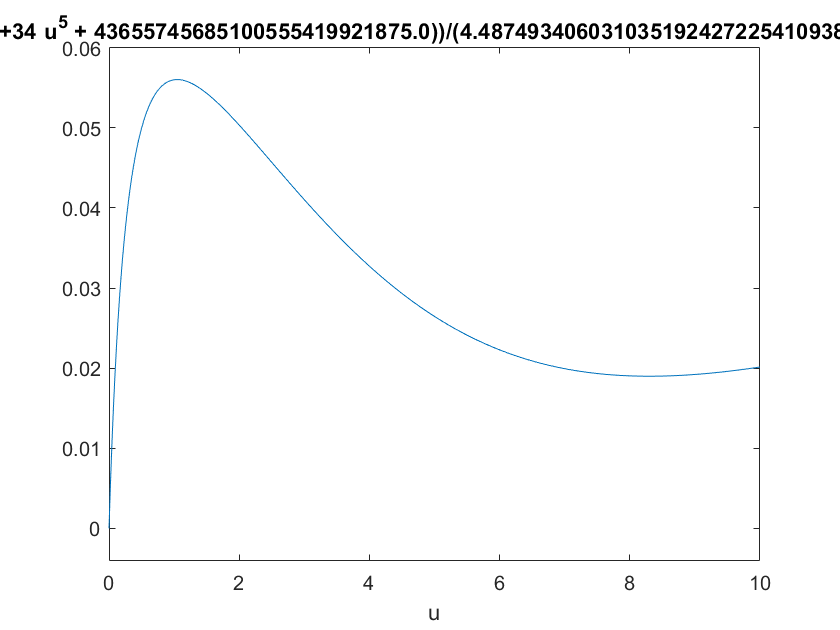

figure
ezplot(J,[0,10])

Adot = vpa(simplify(diff(A,u)),5)

$$Adot = 0.0028113\,u^{4}-0.0086854\,u^{3}-0.053701\,u^{2}+0.45332\,u+0.72971$$

Bdot = vpa(simplify(diff(B,u)),5)

$$Bdot = 0.029304\,u^{4}+0.24929\,u^{3}+1.6518\,u^{2}+8.4076\,u+8.2453$$

vpasolve(A*Bdot==B*Adot,u,[0,10])

$$ans = \left(\begin{array}{c} 1.0485907006261532731824501978103\\ 8.2988446510893728297692029787947 \end{array}\right)$$

Addot = vpa(simplify(diff(Adot,u)),5)

$$Addot = 0.011245\,u^{3}-0.026056\,u^{2}-0.1074\,u+0.45332$$

Bddot = vpa(simplify(diff(Bdot,u)),5)

$$Bddot = 0.11722\,u^{3}+0.74788\,u^{2}+3.3037\,u+8.4076$$

C = vpa(simplify(B*Addot - A*Bddot),5)

$$C = 0.00038215\,u^{7}+0.005803\,u^{6}+0.018154\,u^{5}-0.22536\,u^{4}-1.5301\,u^{3}-3.3673\,u^{2}-2.6903\,u+1.2367$$

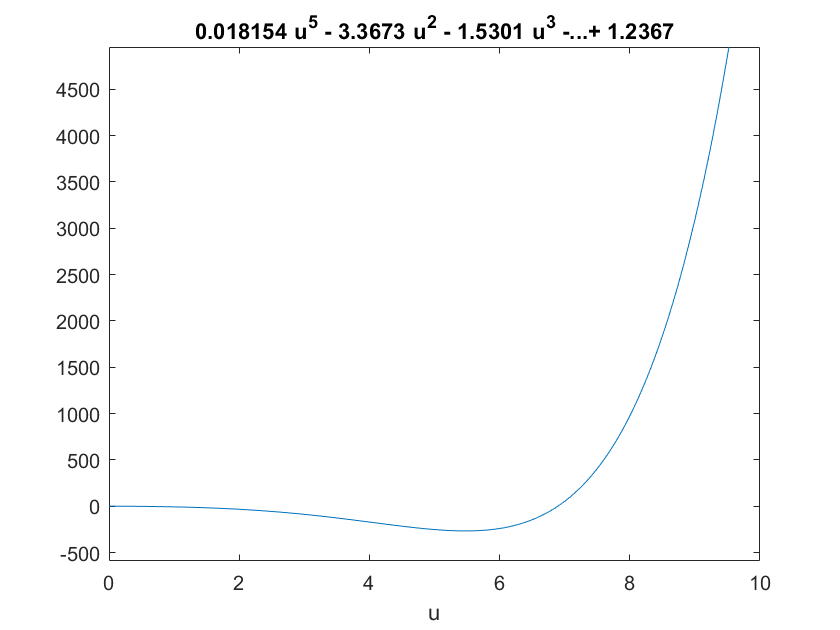

figure
ezplot(C,[0,10])



% with stabel A
% Agent 1 finished dwelling at t = 0.001 at taregt 1
% Solution Found: i=1, j=2, cost=-0.068569, u=0.63004
 
A = (1768001018599217*u)/1125899906842624 + (1491631261260099*log(abs((2775170073191597*exp(-(2842286668281031*u)/4503599627370496))/9007199254740992 + 8037600881749939/9007199254740992)))/281474976710656 - 8720852316336059/9007199254740992;
B = (127173751334885961*u)/4503599627370496 + (5840097815520821*exp(- (8488050406509199*u)/72057594037927936 - 56416124694879172517639103826931/1298074214633706907132624082305024))/70368744177664 + (1566262512155597*exp(- (4734183539382577*u)/9007199254740992 - 31465916917910144940727169118413/162259276829213363391578010288128))/1125899906842624 + (1379353855740199*exp(- (1013017794093903*u)/36028797018963968 - 6733058294034899873251666102707/649037107316853453566312041152512))/4398046511104 + (1105001771684693*exp(- (1984302092869915*u)/4503599627370496 - 13188733447884657501290123261135/81129638414606681695789005144064))/281474976710656 + (8852661329363497*exp(- (4203268881070557*u)/9007199254740992 - 27937174022757119019552810633033/162259276829213363391578010288128))/2251799813685248 - 32064258978344405996488115146094971/81129638414606681695789005144064;
A = vpa(A,5)

$$A = 1.5703\,u+5.2993\,\log\left(0.30811\,{\mathrm{e}}^{-0.63111\,u}+0.89235\right)-0.96821$$

B = vpa(B,5)

$$B = 28.238\,u+1.3911\,{\mathrm{e}}^{-0.5256\,u-0.19392}+3.9258\,{\mathrm{e}}^{-0.4406\,u-0.16256}+313.63\,{\mathrm{e}}^{-0.028117\,u-0.010374}+3.9314\,{\mathrm{e}}^{-0.46666\,u-0.17218}+82.993\,{\mathrm{e}}^{-0.1178\,u-0.043461}-395.22$$

Adot = vpa(simplify(diff(A,u)),5)

$$Adot = \frac{1.4013e+33\,{\mathrm{e}}^{0.63111\,u}-5.4664e+32}{8.9235e+32\,{\mathrm{e}}^{0.63111\,u}+3.0811e+32}$$

Bdot = vpa(simplify(diff(B,u)),5)

$$Bdot = 28.238-1.4702\,{\mathrm{e}}^{-0.4406\,u}-8.7273\,{\mathrm{e}}^{-0.028117\,u}-1.5444\,{\mathrm{e}}^{-0.46666\,u}-9.3604\,{\mathrm{e}}^{-0.1178\,u}-0.60228\,{\mathrm{e}}^{-0.5256\,u}$$

vpasolve(A*Bdot==B*Adot,u,[0,10])

$$ans = 3.9646125637475777831146648722445$$

Addot = vpa(simplify(diff(Adot,u)),5)

$$Addot = \frac{8.8436e+32\,{\mathrm{e}}^{0.63111\,u}}{8.9235e+32\,{\mathrm{e}}^{0.63111\,u}+3.0811e+32}-\frac{5.6318e+32\,{\mathrm{e}}^{0.63111\,u}\,\left(1.4013e+33\,{\mathrm{e}}^{0.63111\,u}-5.4664e+32\right)}{{\left(8.9235e+32\,{\mathrm{e}}^{0.63111\,u}+3.0811e+32\right)}^{2}}$$

Bddot = vpa(simplify(diff(Bdot,u)),5)

$$Bddot = 0.31656\,{\mathrm{e}}^{-0.5256\,u}+0.64777\,{\mathrm{e}}^{-0.4406\,u}+0.24538\,{\mathrm{e}}^{-0.028117\,u}+0.72072\,{\mathrm{e}}^{-0.46666\,u}+1.1026\,{\mathrm{e}}^{-0.1178\,u}$$

C = vpa(simplify(B*Addot - A*Bddot),5)

$$C = \frac{\left(5.8033e+65\,{\mathrm{e}}^{0.63111\,u}+1.7426e+33\,{\mathrm{e}}^{1.2622\,u}\right)\,\left(28.238\,u+1.1459\,{\mathrm{e}}^{-0.5256\,u}+3.3367\,{\mathrm{e}}^{-0.4406\,u}+310.39\,{\mathrm{e}}^{-0.028117\,u}+3.3095\,{\mathrm{e}}^{-0.46666\,u}+79.463\,{\mathrm{e}}^{-0.1178\,u}-395.22\right)}{5.4988e+65\,{\mathrm{e}}^{0.63111\,u}+7.9629e+65\,{\mathrm{e}}^{1.2622\,u}+9.4929e+64}-1.0\,\left(1.5703\,u+\log\left({\left(0.30811\,{\mathrm{e}}^{-0.63111\,u}+0.89235\right)}^{5.2993}\right)-0.96821\right)\,\left(0.31656\,{\mathrm{e}}^{-0.5256\,u}+0.64777\,{\mathrm{e}}^{-0.4406\,u}+0.24538\,{\mathrm{e}}^{-0.028117\,u}+0.72072\,{\mathrm{e}}^{-0.46666\,u}+1.1026\,{\mathrm{e}}^{-0.1178\,u}\right)$$

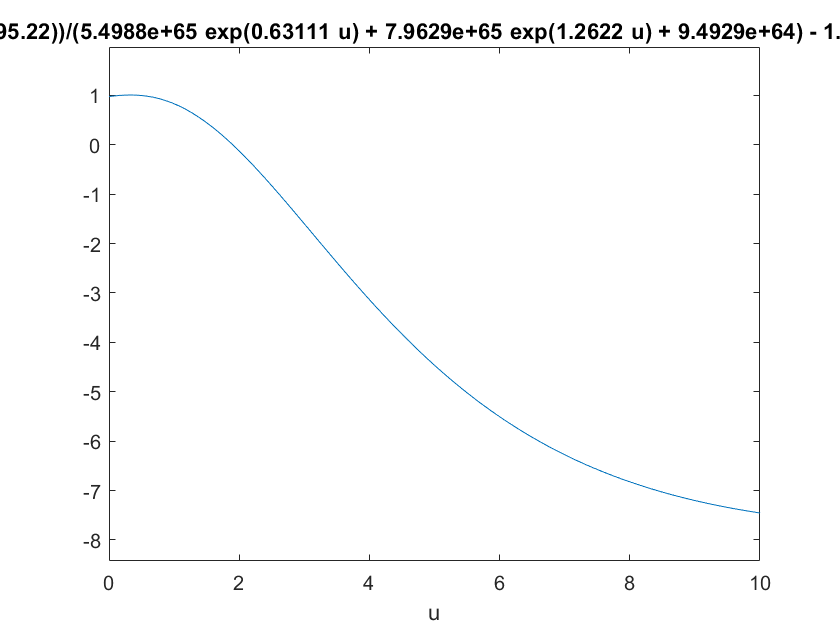

figure
ezplot(C,[0,10])



% No sol case
% Target 7 observation error.
% Agent 1 finished dwelling at t = 0.572 at taregt 7
% No Solution! i=7, j=1, cost=0
 
A = (7399254277060949*u)/2251799813685248 + (3731237466964757*log(6869291714810381/4651212283438094 - (4436158862744573*exp(-(6330999558834973*u)/4503599627370496))/9302424566876188))/1125899906842624

$$A = \frac{7399254277060949\,u}{2251799813685248}+\frac{3731237466964757\,\log\left(\frac{6651285239608871}{4503599627370496}-\frac{4436158862744573\,{\mathrm{e}}^{-\frac{6330999558834973\,u}{4503599627370496}}}{9302424566876188}\right)}{1125899906842624}$$

B = (7156330095647461*exp((4734183539382577*u)/9007199254740992 + 13459163478556785927400301454525/40564819207303340847894502572032))/1125899906842624 - (147847481859838377*u)/4503599627370496 + (8006020572883345*exp((8488050406509199*u)/72057594037927936 + 24131311573597528594117024668675/324518553658426726783156020576256))/70368744177664 + (8309026921958541*exp((4203268881070557*u)/9007199254740992 + 11949786598691346970612117628025/40564819207303340847894502572032))/562949953421312 + (6657017411876817*exp((5544732997894649*u)/144115188075855872 + 15763534988198854047781119389925/649037107316853453566312041152512))/17592186044416 + (955185273664295*exp((1984302092869915*u)/4503599627370496 + 5641320417049491205370810937375/20282409603651670423947251286016))/70368744177664 - 11052311051480947725960039406803157/20282409603651670423947251286016

$$B = \frac{8309026921958541\,{\mathrm{e}}^{\frac{4203268881070557\,u}{9007199254740992}+\frac{1326692822122427}{4503599627370496}}}{562949953421312}-\frac{4620233808119949\,u}{140737488355328}+\frac{8006020572883345\,{\mathrm{e}}^{\frac{8488050406509199\,u}{72057594037927936}+\frac{5358227544682299}{72057594037927936}}}{70368744177664}+\frac{7156330095647461\,{\mathrm{e}}^{\frac{4734183539382577\,u}{9007199254740992}+\frac{5977069274435103}{18014398509481984}}}{1125899906842624}+\frac{955185273664295\,{\mathrm{e}}^{\frac{1984302092869915\,u}{4503599627370496}+\frac{5010499053037069}{18014398509481984}}}{70368744177664}+\frac{6657017411876817\,{\mathrm{e}}^{\frac{5544732997894649\,u}{144115188075855872}+\frac{7000415797353045}{288230376151711744}}}{17592186044416}-\frac{4793175861200477}{8796093022208}$$


% A = vpa(taylor(A,u),5)
% B = vpa(taylor(B,u),5)
J = simplifyFraction(A/(A+B))

$$J = \begin{array}{l} \frac{7399254277060949\,u+\sigma_{1}}{33236107687834164\,{\mathrm{e}}^{\frac{4203268881070557\,u}{9007199254740992}+\frac{1326692822122427}{4503599627370496}}-66524486652858235\,u+256192658332267040\,{\mathrm{e}}^{\frac{8488050406509199\,u}{72057594037927936}+\frac{5358227544682299}{72057594037927936}}+14312660191294922\,{\mathrm{e}}^{\frac{4734183539382577\,u}{9007199254740992}+\frac{5977069274435103}{18014398509481984}}+30565928757257440\,{\mathrm{e}}^{\frac{1984302092869915\,u}{4503599627370496}+\frac{5010499053037069}{18014398509481984}}+852098228720232576\,{\mathrm{e}}^{\frac{5544732997894649\,u}{144115188075855872}+\frac{7000415797353045}{288230376151711744}}+\sigma_{1}-1227053020467322112}\\ \mathrm{where}\\ \sigma_{1}=7462474933929514\,\log\left(\frac{{\mathrm{e}}^{-\frac{6330999558834973\,u}{4503599627370496}}\,\left(15468269803559633533361850865937\,{\mathrm{e}}^{\frac{6330999558834973\,u}{4503599627370496}}-4994670850303195568271421079552\right)}{10473598953256436981077809037312}\right) \end{array}$$

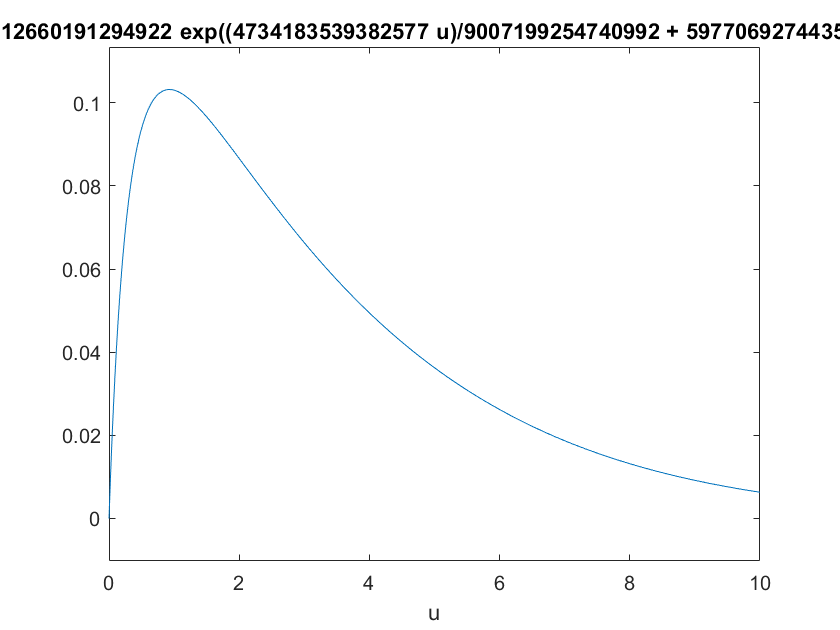

figure
ezplot(J,[0,10])

Adot = vpa(simplify(diff(A,u)),5)

$$Adot = \frac{2.2204e-16\,\left(2.2891e+47\,{\mathrm{e}}^{1.4058\,u}+3.0879e+46\right)}{1.5468e+31\,{\mathrm{e}}^{1.4058\,u}-4.9947e+30}$$

Bdot = vpa(simplify(diff(B,u)),5)

$$Bdot = 3.3408\,{\mathrm{e}}^{0.5256\,u+0.33179}+14.559\,{\mathrm{e}}^{0.038474\,u+0.024288}+5.9808\,{\mathrm{e}}^{0.4406\,u+0.27814}+6.8878\,{\mathrm{e}}^{0.46666\,u+0.29458}+13.402\,{\mathrm{e}}^{0.1178\,u+0.07436}-32.829$$

tic
uSol = vpasolve(A*Bdot==B*Adot,u,[0,10])

$$uSol = 0.92725077316405081342682155924253$$

toc

Elapsed time is 0.277117 seconds.


Addot = vpa(simplify(diff(Adot,u)),5)

$$Addot = \frac{7.1452e+31\,{\mathrm{e}}^{1.4058\,u}}{1.5468e+31\,{\mathrm{e}}^{1.4058\,u}-4.9947e+30}-\frac{4.8283e+15\,{\mathrm{e}}^{1.4058\,u}\,\left(2.2891e+47\,{\mathrm{e}}^{1.4058\,u}+3.0879e+46\right)}{{\left(1.5468e+31\,{\mathrm{e}}^{1.4058\,u}-4.9947e+30\right)}^{2}}$$

Bddot = vpa(simplify(diff(Bdot,u)),5)

$$Bddot = 2.4468\,{\mathrm{e}}^{0.5256\,u}+0.57392\,{\mathrm{e}}^{0.038474\,u}+3.4801\,{\mathrm{e}}^{0.4406\,u}+4.3153\,{\mathrm{e}}^{0.46666\,u}+1.7005\,{\mathrm{e}}^{0.1178\,u}$$

C = vpa(simplify(B*Addot - A*Bddot),5)

$$C = \begin{array}{l} \left(\frac{7.1452e+31\,{\mathrm{e}}^{1.4058\,u}}{\sigma_{1}}-\frac{4.8283e+15\,{\mathrm{e}}^{1.4058\,u}\,\left(2.2891e+47\,{\mathrm{e}}^{1.4058\,u}+3.0879e+46\right)}{{\sigma_{1}}^{2}}\right)\,\left(6.3561\,{\mathrm{e}}^{0.5256\,u+0.33179}-32.829\,u+378.41\,{\mathrm{e}}^{0.038474\,u+0.024288}+13.574\,{\mathrm{e}}^{0.4406\,u+0.27814}+14.76\,{\mathrm{e}}^{0.46666\,u+0.29458}+113.77\,{\mathrm{e}}^{0.1178\,u+0.07436}-544.92\right)-1.0\,\left(3.2859\,u+3.314\,\log\left(1.4769-0.47688\,{\mathrm{e}}^{-1.4058\,u}\right)\right)\,\left(2.4468\,{\mathrm{e}}^{0.5256\,u}+0.57392\,{\mathrm{e}}^{0.038474\,u}+3.4801\,{\mathrm{e}}^{0.4406\,u}+4.3153\,{\mathrm{e}}^{0.46666\,u}+1.7005\,{\mathrm{e}}^{0.1178\,u}\right)\\ \mathrm{where}\\ \sigma_{1}=1.5468e+31\,{\mathrm{e}}^{1.4058\,u}-4.9947e+30 \end{array}$$

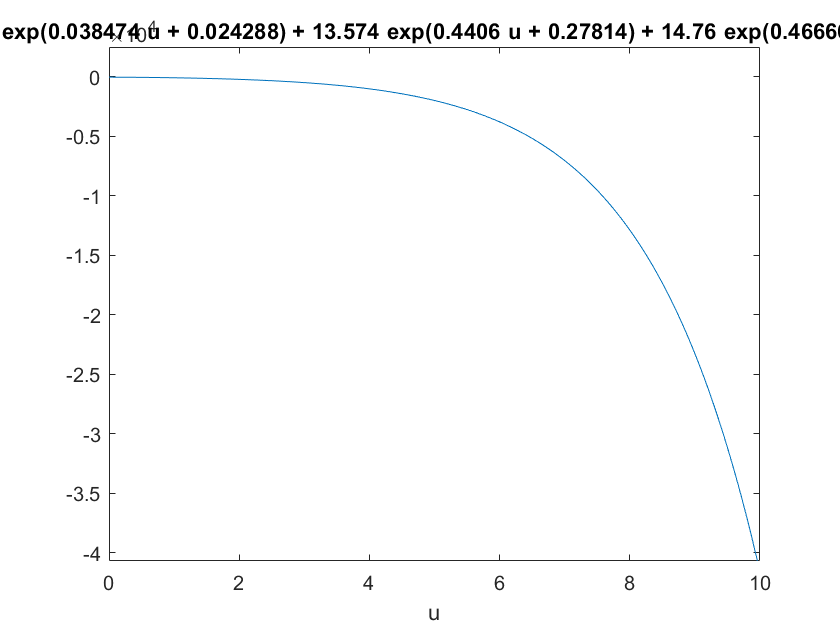

figure
ezplot(C,[0,10])

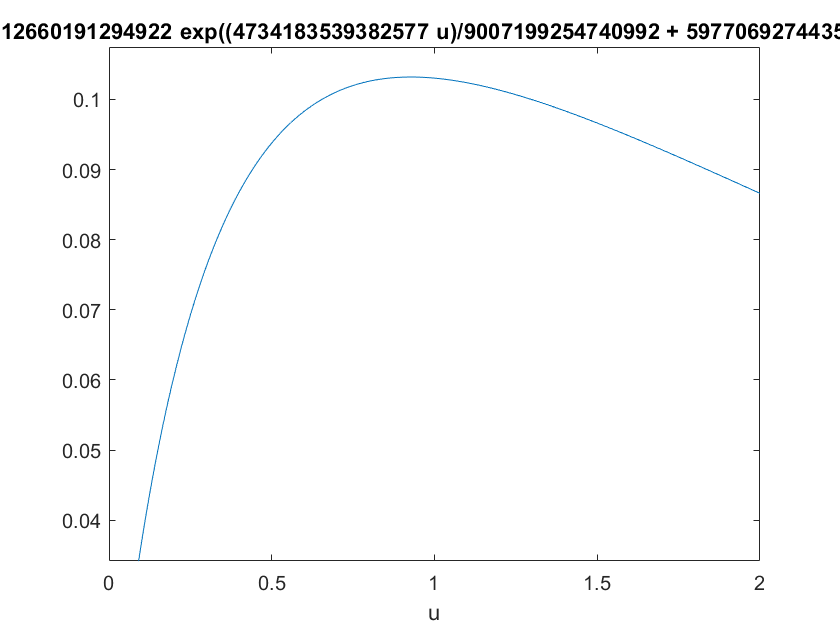


figure
ezplot(J,[0,2])



% gradient descent

tic
JFun = matlabFunction(J);
JFun(double(uSol))

ans = 0.1032

DJFun = matlabFunction(diff(J,u));

u_ik = 0.5;
Jval = JFun(u_ik);
beta = 0.1;
for k = 1:1:100000
    grad = DJFun(u_ik);
    u_ik = u_ik + beta*grad;
    if u_ik<0
        u_ik =0;
    end
    
    Jval2 = JFun(u_ik);
    if abs(Jval-Jval2)<0.0000000001
        k
        u_ik
        Jval2
        break
    end
    Jval = Jval2;
end

k = 963

u_ik = 0.9268

Jval2 = 0.1032

u_ik

u_ik = 0.9268

toc

Elapsed time is 0.336505 seconds.


syms u_i u_j
A = 4.12051*u_i + 1.77419*u_j + 5.29934*log(4.243*exp(0.0384743*u_i + 0.0141954) - 0.833015*exp(-0.631114*u_j)*(5.09354*exp(0.0384743*u_i + 0.0141954) - 5.54146) - 3.61612) + 5.70437*log(0.631095*exp(-0.919086*u_i) + 0.368905)

$$A = \begin{array}{l} \frac{4639281825144101\,u_{i}}{1125899906842624}+\frac{1997560355721115\,u_{j}}{1125899906842624}+\frac{6422549651595859\,\log\left(\frac{2842199206835383\,{\mathrm{e}}^{-\frac{8278390734242879\,u_{i}}{9007199254740992}}}{4503599627370496}+\frac{6645601682140451}{18014398509481984}\right)}{1125899906842624}+\frac{5966526412327391\,\log\left(\frac{4243\,\sigma_{1}}{1000}-\frac{7503132087188067\,{\mathrm{e}}^{-\frac{2842284775228303\,u_{j}}{4503599627370496}}\,\left(\frac{5734816211499179\,\sigma_{1}}{1125899906842624}-\frac{6239129297772127}{1125899906842624}\right)}{9007199254740992}-\frac{90403}{25000}\right)}{1125899906842624}\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{\frac{2772365490293451\,u_{i}}{72057594037927936}+\frac{4091545481624009}{288230376151711744}} \end{array}$$

B = 368.835*exp(0.0384743*u_i + 0.0141954) - 28.2382*u_j - 40.3602*u_i + 10.1233*exp(0.440604*u_i + 0.440604*u_j + 0.162564) + 331.804*exp(0.0281169*u_i + 0.0281169*u_j + 0.0103739) + 10.8261*exp(0.466657*u_i + 0.466657*u_j + 0.172176) + 105.193*exp(0.117795*u_i + 0.117795*u_j + 0.0434614) + (4.93038e-32*(8.23216e+47*exp(0.919086*u_i) + 1.04473e+47)*(exp(0.5256*u_j + 0.193924) - 1.0))/(3.76713e+15*exp(0.919086*u_i) + 6.44451e+15) - 842.241

$$B = \begin{array}{l} \frac{7402299306281009\,{\mathrm{e}}^{\frac{8488024289697721\,u_{i}}{72057594037927936}+\frac{8488024289697721\,u_{j}}{72057594037927936}+\frac{3131723917520001}{72057594037927936}}}{70368744177664}-\frac{3974173343675423\,u_{j}}{140737488355328}-\frac{5680193177518709\,u_{i}}{140737488355328}+\frac{356181953966873\,{\mathrm{e}}^{\frac{992152005108975\,u_{i}}{2251799813685248}+\frac{992152005108975\,u_{j}}{2251799813685248}+\frac{2928492679295429}{18014398509481984}}}{35184372088832}+\frac{73767\,{\mathrm{e}}^{\frac{2772365490293451\,u_{i}}{72057594037927936}+\frac{4091545481624009}{288230376151711744}}}{200}+\frac{82951\,{\mathrm{e}}^{\frac{253254520725627\,u_{i}}{9007199254740992}+\frac{253254520725627\,u_{j}}{9007199254740992}+\frac{5980146198320485}{576460752303423488}}}{250}+\frac{3047276245367233\,{\mathrm{e}}^{\frac{4203272582619667\,u_{i}}{9007199254740992}+\frac{4203272582619667\,u_{j}}{9007199254740992}+\frac{10761}{62500}}}{281474976710656}+\frac{\left({\mathrm{e}}^{\frac{657\,u_{j}}{1250}+\frac{6986848433105569}{36028797018963968}}-1\right)\,\left(\frac{45697661776677230516074615210485\,\sigma_{1}}{1125899906842624}+\frac{46395325832294806819119341176833}{9007199254740992}\right)}{3767130000000000\,\sigma_{1}+6444510000000000}-\frac{463026886444843}{549755813888}\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{\frac{8278390734242879\,u_{i}}{9007199254740992}} \end{array}$$

J = A/(B+A)

figure
J_i = subs(J,u_j,0)

$$J\_i = \begin{array}{l} \frac{\frac{4639281825144101\,u_{i}}{1125899906842624}+\sigma_{3}+\sigma_{1}}{\frac{7402299306281009\,{\mathrm{e}}^{\frac{8488024289697721\,u_{i}}{72057594037927936}+\frac{3131723917520001}{72057594037927936}}}{70368744177664}-\frac{40802263595005571\,u_{i}}{1125899906842624}+\sigma_{3}+\sigma_{1}+\frac{3047276245367233\,{\mathrm{e}}^{\frac{4203272582619667\,u_{i}}{9007199254740992}+\frac{10761}{62500}}}{281474976710656}+\frac{82951\,{\mathrm{e}}^{\frac{253254520725627\,u_{i}}{9007199254740992}+\frac{5980146198320485}{576460752303423488}}}{250}+\frac{73767\,\sigma_{4}}{200}+\frac{356181953966873\,{\mathrm{e}}^{\frac{992152005108975\,u_{i}}{2251799813685248}+\frac{2928492679295429}{18014398509481984}}}{35184372088832}+\frac{\left({\mathrm{e}}^{6986848433105569/36028797018963968}-1\right)\,\left(\frac{45697661776677230516074615210485\,\sigma_{2}}{1125899906842624}+\frac{46395325832294806819119341176833}{9007199254740992}\right)}{3767130000000000\,\sigma_{2}+6444510000000000}-\frac{463026886444843}{549755813888}}\\ \mathrm{where}\\ \sigma_{1}=\frac{6422549651595859\,\log\left(\frac{2842199206835383\,{\mathrm{e}}^{-\frac{8278390734242879\,u_{i}}{9007199254740992}}}{4503599627370496}+\frac{6645601682140451}{18014398509481984}\right)}{1125899906842624}\\ \sigma_{2}={\mathrm{e}}^{\frac{8278390734242879\,u_{i}}{9007199254740992}}\\ \sigma_{3}=\frac{5966526412327391\,\log\left(\frac{6055440152599362438063286243\,\sigma_{4}}{1267650600228229401496703205376000}+\frac{31691242882033621283940913900984097}{31691265005705735037417580134400000}\right)}{1125899906842624}\\ \sigma_{4}={\mathrm{e}}^{\frac{2772365490293451\,u_{i}}{72057594037927936}+\frac{4091545481624009}{288230376151711744}} \end{array}$$

J_j = subs(J,u_i,0)

$$J\_j = \begin{array}{l} \frac{\frac{1997560355721115\,u_{j}}{1125899906842624}+\sigma_{1}+\sigma_{2}}{\frac{137325540015237550315905420953571\,{\mathrm{e}}^{\frac{657\,u_{j}}{1250}+\frac{6986848433105569}{36028797018963968}}}{30659425399227767848960000000000}-\frac{29795826393682269\,u_{j}}{1125899906842624}+\frac{7402299306281009\,{\mathrm{e}}^{\frac{8488024289697721\,u_{j}}{72057594037927936}+\frac{3131723917520001}{72057594037927936}}}{70368744177664}+\sigma_{1}+\frac{3047276245367233\,{\mathrm{e}}^{\frac{4203272582619667\,u_{j}}{9007199254740992}+\frac{10761}{62500}}}{281474976710656}+\frac{82951\,{\mathrm{e}}^{\frac{253254520725627\,u_{j}}{9007199254740992}+\frac{5980146198320485}{576460752303423488}}}{250}+\sigma_{2}+\frac{73767\,{\mathrm{e}}^{4091545481624009/288230376151711744}}{200}+\frac{356181953966873\,{\mathrm{e}}^{\frac{992152005108975\,u_{j}}{2251799813685248}+\frac{2928492679295429}{18014398509481984}}}{35184372088832}-\frac{25959950647686231525038465420953571}{30659425399227767848960000000000}}\\ \mathrm{where}\\ \sigma_{1}=\frac{5966526412327391\,\log\left(\frac{4243\,{\mathrm{e}}^{4091545481624009/288230376151711744}}{1000}-\frac{7503132087188067\,{\mathrm{e}}^{-\frac{2842284775228303\,u_{j}}{4503599627370496}}\,\left(\frac{5734816211499179\,{\mathrm{e}}^{4091545481624009/288230376151711744}}{1125899906842624}-\frac{6239129297772127}{1125899906842624}\right)}{9007199254740992}-\frac{90403}{25000}\right)}{1125899906842624}\\ \sigma_{2}=\frac{6422549651595859\,\log\left(\frac{18014398509481983}{18014398509481984}\right)}{1125899906842624} \end{array}$$

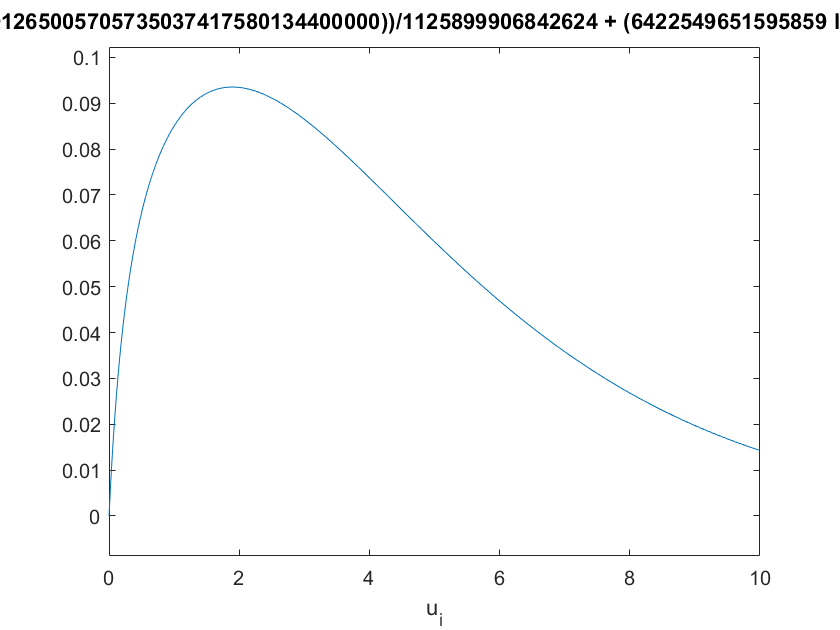

figure
ezplot(J_i,[0,10])

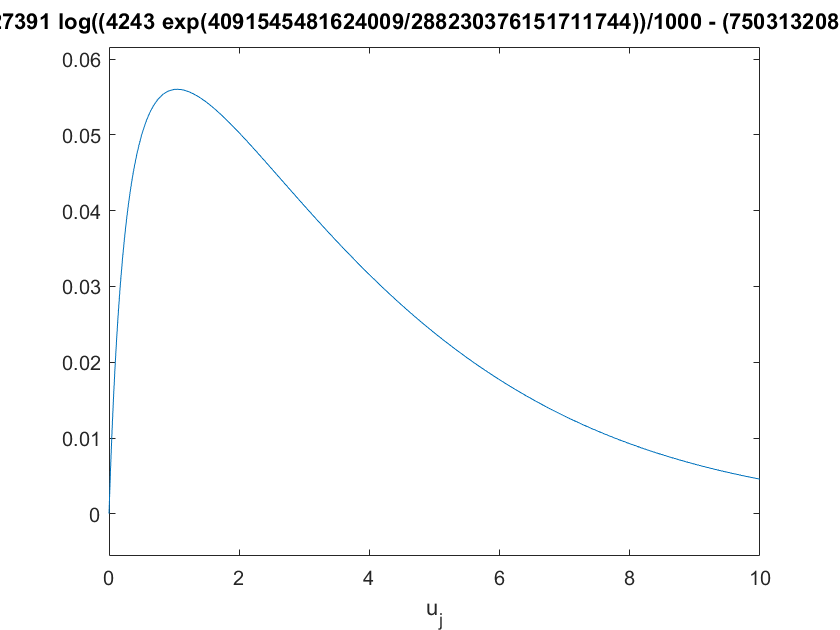

figure
ezplot(J_j,[0,10])


DJ_i = diff(J,u_i);
DJ_j = diff(J,u_j);
tic
% vpasolve([DJ_i==0,DJ_j==0],[u_i,u_j],[0,10;0,10])
toc

Elapsed time is 0.003309 seconds.



% grad descent
tic
JFun = matlabFunction(J);
DJ_iFun = matlabFunction(DJ_i);
DJ_jFun = matlabFunction(DJ_j);

u_ik = 1; u_jk = 1;
Jval = JFun(u_ik,u_jk)

Jval = 0.0652

beta = 0.1;
for k = 1:1:10000
    grad_i = DJ_iFun(u_ik,u_jk);
    u_ik = u_ik + beta*grad_i;
    if u_ik<0
        u_ik =0;
    end
    
    grad_j = DJ_jFun(u_ik,u_jk);
    u_jk = u_jk + beta*grad_j;
    if u_jk<0
        u_jk =0;
    end
    
    Jval2 = JFun(u_ik,u_jk);
    if abs(Jval-Jval2)<0.0000001
        u_ik
        u_jk
        Jval2
        k
        break
    end
    Jval = Jval2;
end

u_ik = 1.8320

u_jk = 0

Jval2 = 0.0935

k = 1677

u_ik

u_ik = 1.8320

u_jk

u_jk = 0

Jval 

Jval = 0.0935

toc

Elapsed time is 0.531444 seconds.
